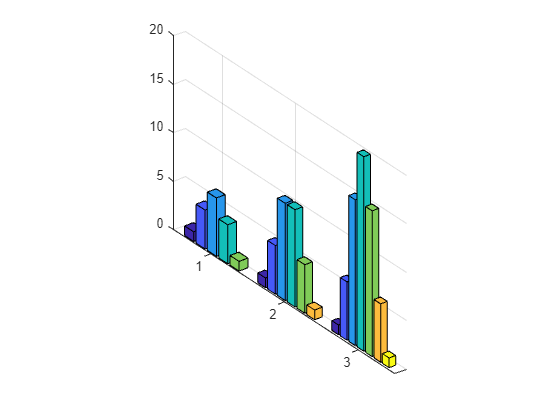

% bar3nDemo
X{1}=[1 4  6  4  1];
X{2}=[1 5 10 10  5 1];
X{3}=[1 6 15 20 15 6 1];
bar3n(X);

function hdlSet=bar3n(X)
ax=gca;
ax.Projection='perspective';

for i=1:length(X)
    SE=nan(length(X),length(X{i}));
    SE(i,:)=X{i};
    hdlSet{i}=bar3(SE,'grouped');
    if i==1
        hold on;
    end
end

for i=1:length(X)
    for j=1:length(hdlSet{i})
        % 删掉多余的柱状图
        tXData=hdlSet{i}(j).XData;
        hdlSet{i}(j).XData=nan.*ones(size(hdlSet{i}(j).XData));
        hdlSet{i}(j).XData((i-1)*6+1:i*6,:)=tXData((i-1)*6+1:i*6,:);
    end
end
end